## Four Bar Mechanism - Position, Velocity and Acceleration Analysis

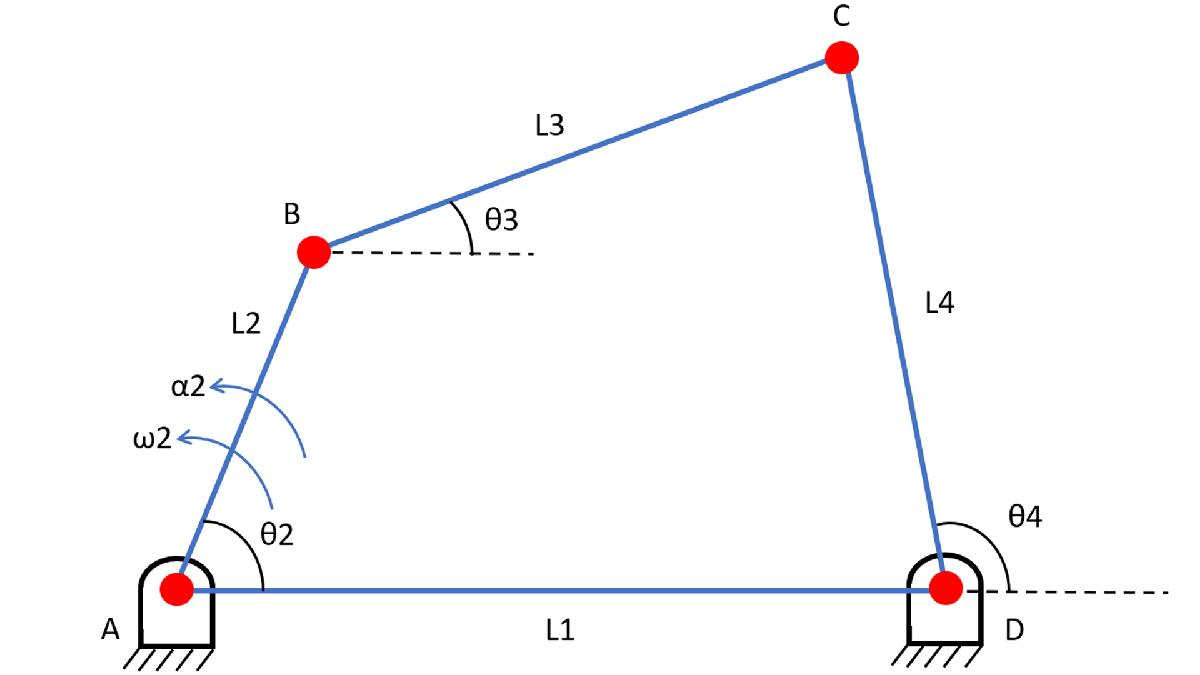

#### Inputs

L1 = 100;
L2 = 50;
L3 = 66;
L4 = 56;
theta_2 = 60;


#### Newton-Raphson's Method

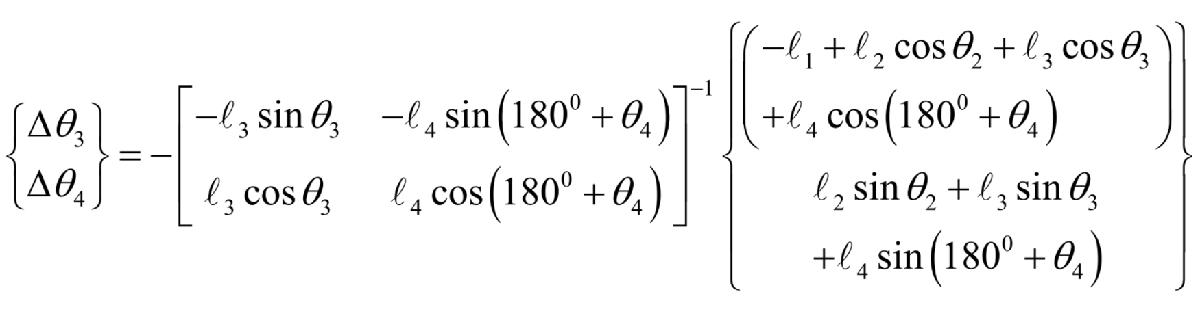

#### Initial Solution

angle_3 = 20;
angle_4 = 70;
iter = 0;
sol = [angle_3;angle_4];

#### While Loop

while iter < 1000
    
    f = [(-L1 + L2*cosd(theta_2) + L3*cosd(sol(1)) + L4*cosd(180+sol(2)));
         (L2*sind(theta_2) + L3*sind(sol(1)) + L4*sind(180+sol(2)))];
    
    df = [(-L3*sind(sol(1))), (-L4*sind(180+sol(2))) ;
          (L3*cosd(sol(1))), (L4*cosd(180+sol(2)))];
    
    sol = sol - (df\f);
    
    iter = iter + 1;

end

theta_3 = sol(1)

theta_3 = 10.2881

theta_4 = sol(2)

theta_4 = 100.3501

### Velocity Analysis

w2 = 10.5;          % In rad/s

% Position vectors
rAB = [L2*cosd(theta_2) L2*sind(theta_2) 0]./1000;
rBC = [L3*cosd(theta_3) L3*sind(theta_3) 0]./1000;
rDC = [L4*cosd(theta_4) L4*sind(theta_4) 0]./1000;

k = [0 0 1];

V_B = w2*cross(k,rAB);
Vel_mag_B = norm(V_B,2)% Magnitude of velocity at point C

Vel_mag_B = 0.5250


syms w3 w4

V_C1 = V_B + w3*cross(k,rBC);
V_C2 = w4*cross(k,rDC);

eqn_vel = V_C1 - V_C2 == 0;
S = solve(eqn_vel,[w3 w4]);

w3 = double(S.w3)

w3 = -5.1502

w4 = double(S.w4)

w4 = 7.1513


V_C = double(subs(V_C2,w4));
Vel_mag_C = norm(V_C,2)             % Magnitude of velocity at point C

Vel_mag_C = 0.4005

### Acceleration Analysis

alpha_2 = -26;             % In rad/s2
a_B = (alpha_2*cross(k,rAB)) - ((w2)^2)*rAB;
acc_mag_B = double(norm(a_B,2))             % Magnitude of acceleration at point B

acc_mag_B = 5.6637


syms alpha_3 alpha_4

a_C1 = a_B + alpha_3*cross(k,rBC) - ((w3)^2)*rBC;
a_C2 = alpha_4*cross(k,rDC) - ((w4)^2)*rDC;

eqn_acc = a_C1 - a_C2 == 0;
R = solve(eqn_acc,[alpha_3 alpha_4]);

alpha3 = double(R.alpha_3)

alpha3 = 32.9850

alpha4 = double(R.alpha_4)

alpha4 = 77.2618


a_C = double(subs(a_C2,alpha4));
acc_mag_C = double(norm(a_C,2))              % Magnitude of acceleration at point C

acc_mag_C = 5.1886